# **Expressing a single Polynomial **

**Numerical Programming**

**mod: 2024.9.19**

# MATLAB Examples

An experiment is conducted that measures the pressure of a gas by heating it in a closed chamber. 

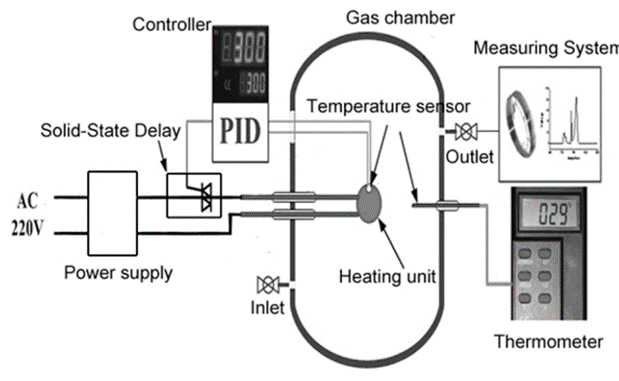

- Predict the pressure at T=100C

- Estimate interpolated value P when T=75

close all 
clear all

T=[0 10 20 30 40 50 60 70 80];
P=[0.94 0.96 1 1.05 1.07 1.09 1.14 1.17 1.21];
n=length(T);

X=T;
Y=P;

## `Linear Interplation`

Interpolation: interpl() Estimate interpolated value P when T=75C

Using a linear interpolation

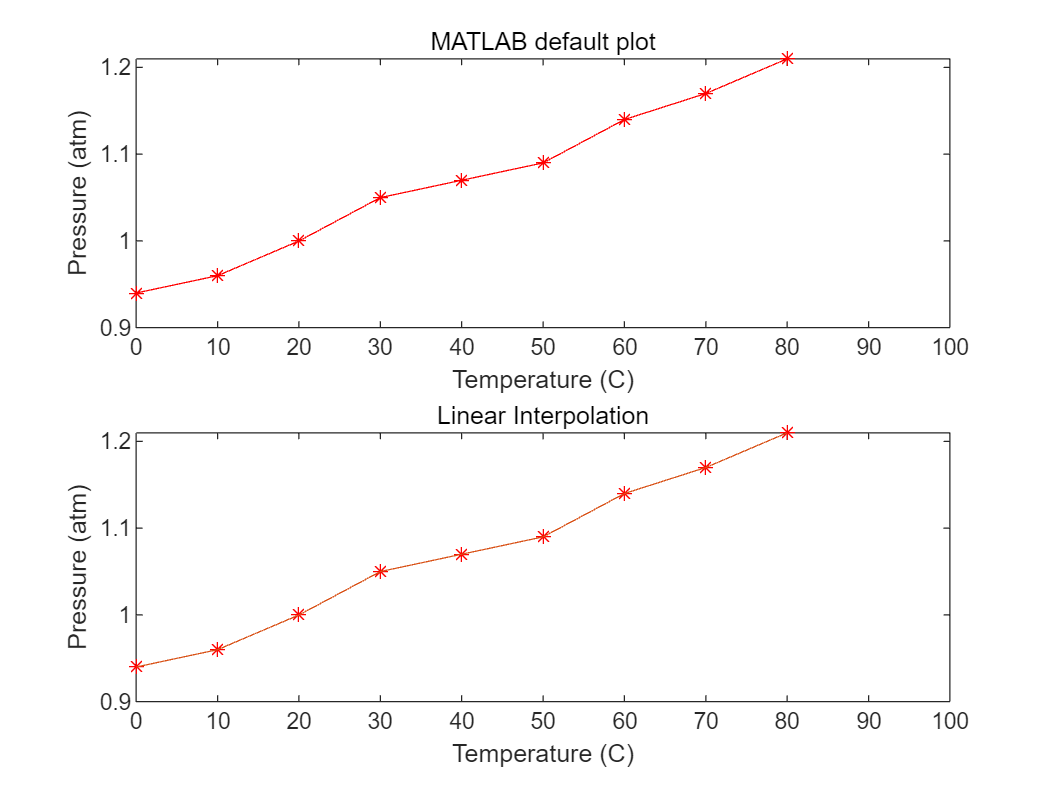

% Interpolation Linear
Yin1 = interp1(X,Y,X,'linear');


figure
subplot(2,1,1)
    % MATLAB default plot
    plot(X,Y,'*-r');
    xlabel('Temperature (C)','fontsize',10)
    ylabel('Pressure (atm)','fontsize',10)    
    title('MATLAB default plot');
    xlim([0.0 100.0])
subplot(2,1,2)
    % Interpolated plot
    plot(X,Y,'*r',X,Yin1);
    xlabel('Temperature (C)','fontsize',10)
    ylabel('Pressure (atm)','fontsize',10)    
    title('Linear Interpolation');
    xlim([0.0 100.0])

## Spline cubic interpolation

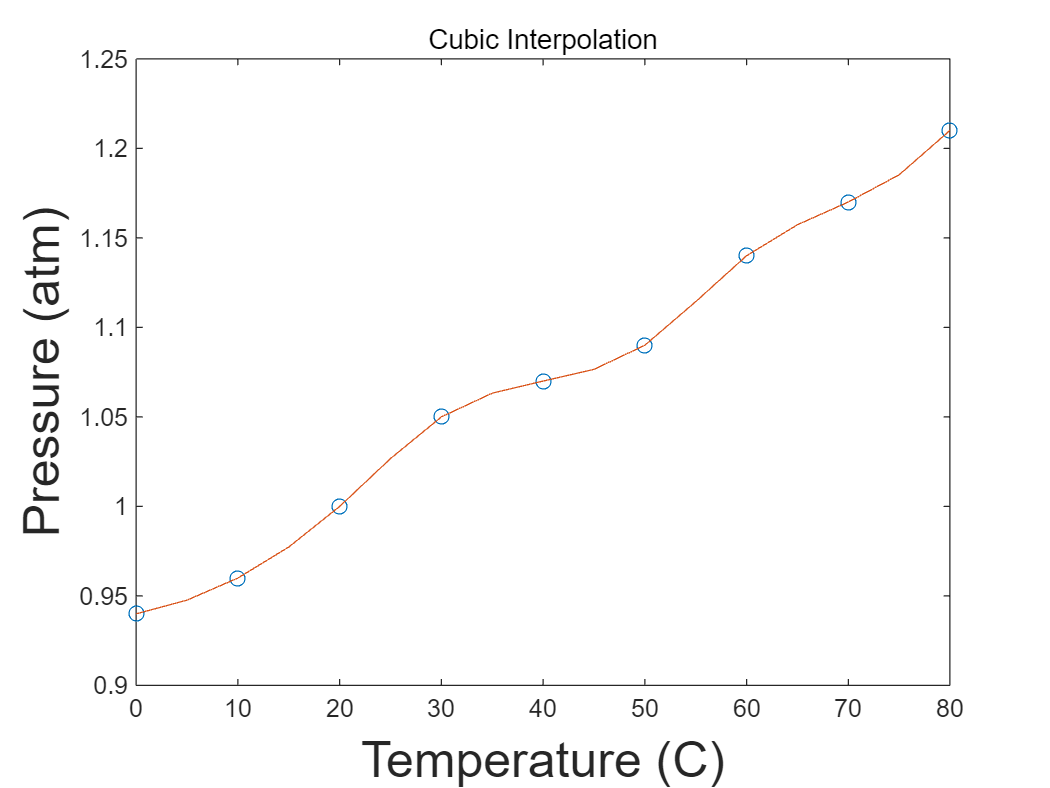

% Interpolation-cubic
figure
Xin=0:5:80;
Yin = interp1(X,Y,Xin,'spline');
plot(X,Y,'o',Xin,Yin);
xlabel('Temperature (C)','fontsize',20)
ylabel('Pressure (atm)','fontsize',20)    
title('Cubic Interpolation');

## Curve Fitting (Comparison)

polyfit() 

Predict the pressure if the temperature is increased to 150C.

Based on Charles's law for ideal gas P=kT, where k is a constant.

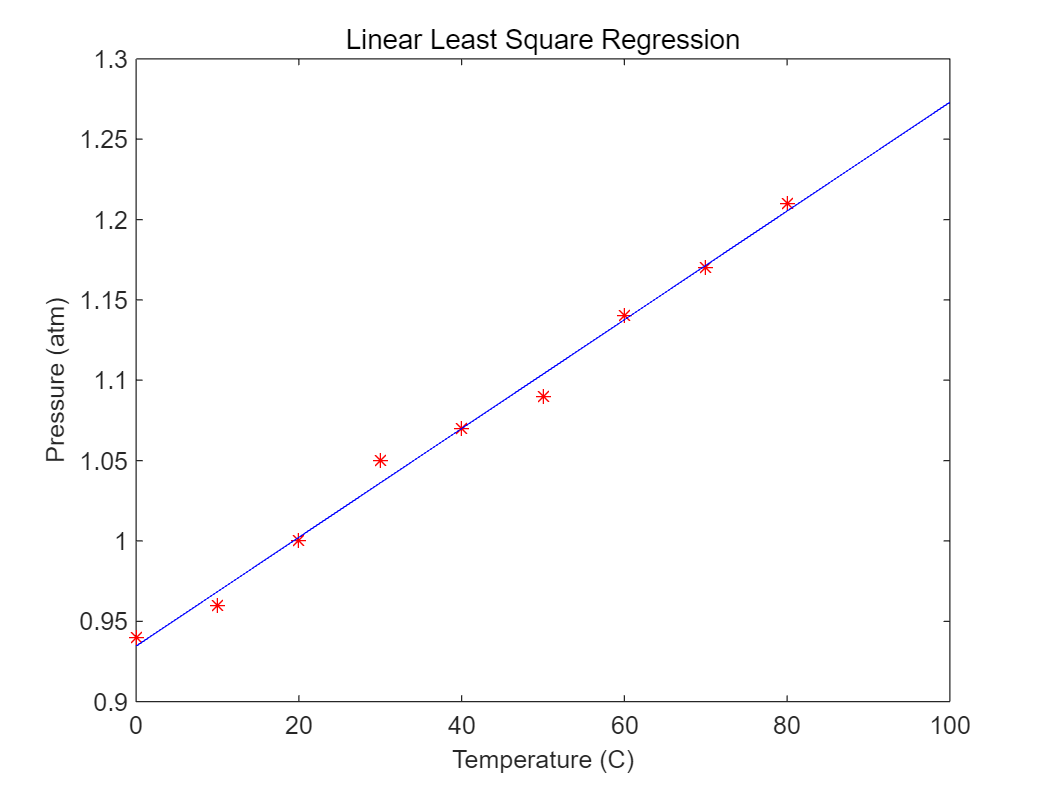

% Polyfit
X=T;
Y=P;

Z=polyfit(X,Y,1); % Curve Fit MATLAB function
t=0:10:100;
Yhat=Z(2)+Z(1).*t;

figure
plot(X,Y, '*r')
hold on
plot(t,Yhat, '-b')
xlabel('Temperature (C)','fontsize',10)
ylabel('Pressure (atm)','fontsize',10)    
title('Linear Least Square Regression');
xlim([0.0 100.0])

# Expressing Polynomial

### 1) Standard Polynomial

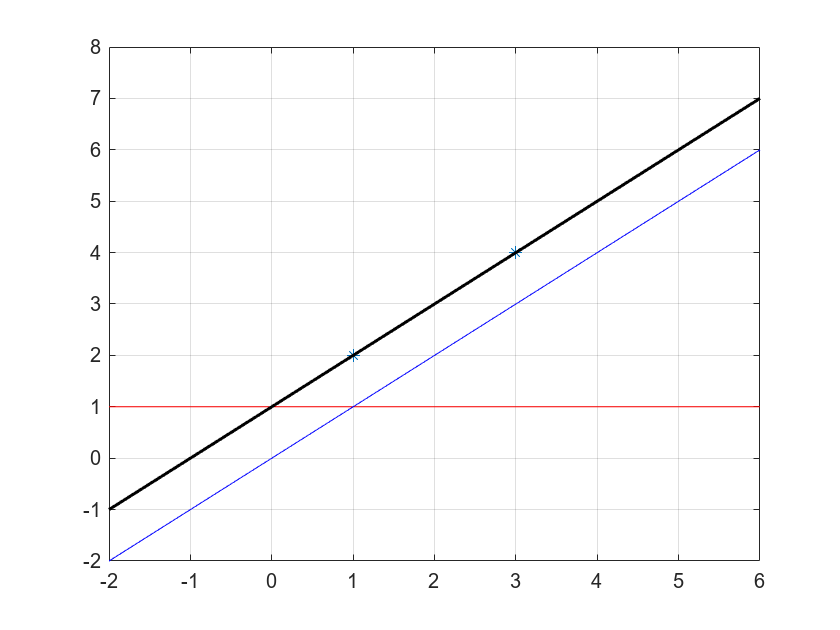

close all
t=-2:0.5:6;
x=[1 3];
y=[2 4];

% Standard
a0=1;
a1=1;

y0=a0*ones(size(t));
y1=a1.*t;

figure
plot(x,y,'*')
hold on
plot(t,y0,'r')
hold on
plot(t,y1,'b')
hold on 
pause (2)
plot(t,y0+y1,'k',"LineWidth",1.5) 
hold off

xlim([-2 6])
ylim([-2 8])
grid on

### 2) Lagrange Polynomial

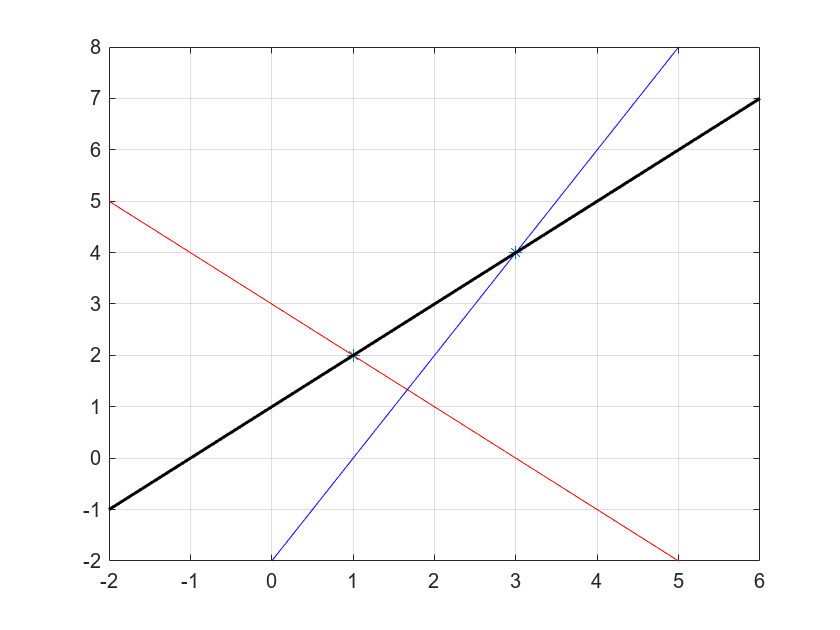

% Lagrange

b0=-1;
b1=2;

y0=b0*(t-x(2));
y1=b1*(t-x(1));

figure
plot(x,y,'*')
hold on
plot(t,y0,'r')
hold on
plot(t,y1,'b')
hold on 
pause (2)
plot(t,y0+y1,'k',"LineWidth",1.5) 
hold off

xlim([-2 6])
ylim([-2 8])
grid on

## 3) Newtonian Polynomial

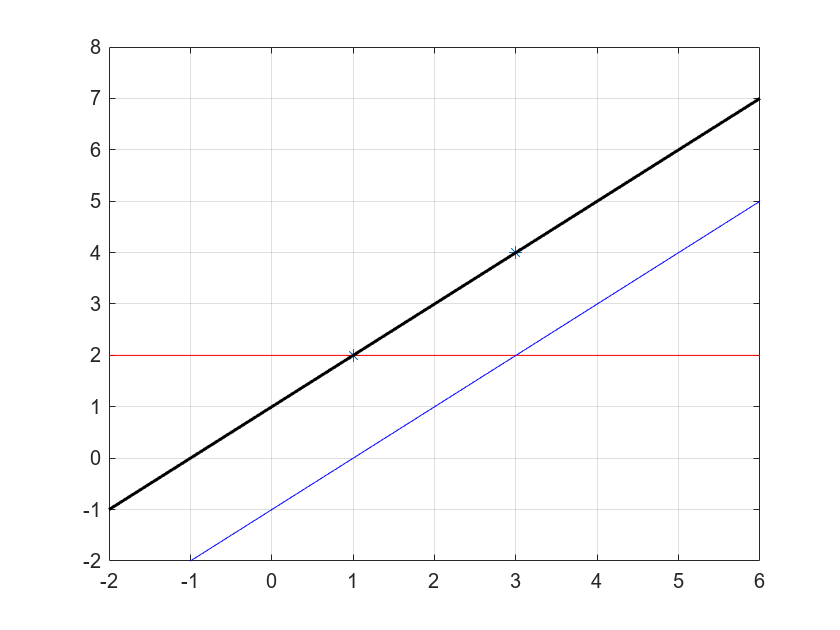

% Newtonian

c0=2;
c1=1;

y0=c0*ones(size(t));
y1=c1*(t-x(1));

figure
plot(x,y,'*')
hold on
plot(t,y0,'r')
hold on
plot(t,y1,'b')
hold on 
pause (2)
plot(t,y0+y1,'k',"LineWidth",1.5) 
hold off

xlim([-2 6])
ylim([-2 8])
grid on